# Exercise 1: Sampling theorem

## Ex 1.1

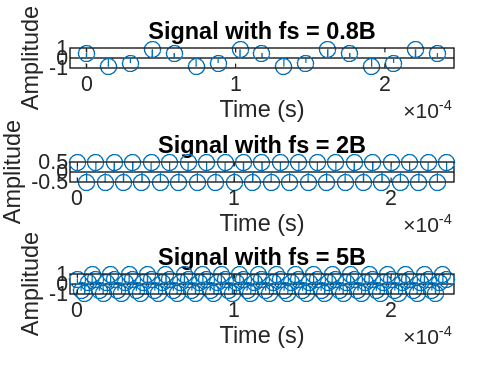

f0 = 85 * 10^3;
B = f0;

fs1 = 0.8 * B;
fs2 = 2 * B;
fs3 = 5 * B;

num_periods = 20;

T0 = 1 / f0;

total_time = num_periods * T0;

% Plot for fs = 0.8B
t1 = 0:1/fs1:total_time;
omega_t1 = cos(2 * pi * f0 * t1 + pi / 3);
subplot(3, 1, 1);
stem(t1, omega_t1, 'o');
title('Signal with fs = 0.8B');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot for fs = 2B
t2 = 0:1/fs2:total_time;
omega_t2 = cos(2 * pi * f0 * t2 + pi / 3);
subplot(3, 1, 2);
stem(t2, omega_t2, 'o');
title('Signal with fs = 2B');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot for fs = 5B
t3 = 0:1/fs3:total_time;
omega_t3 = cos(2 * pi * f0 * t3 + pi / 3);
subplot(3, 1, 3);
stem(t3, omega_t3, 'o');
title('Signal with fs = 5B');
xlabel('Time (s)');
ylabel('Amplitude');

## Ex 1.2

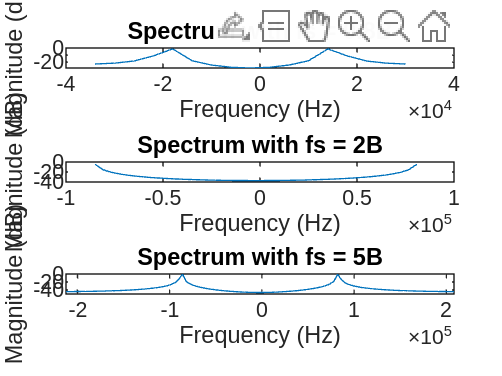

[freq_bins1, dB_values1] = calculateSpectrumdB(omega_t1, fs1);
subplot(3, 1, 1);
plot(freq_bins1, dB_values1);
title('Spectrum with fs = 0.8B');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% For fs = 2B
[freq_bins2, dB_values2] = calculateSpectrumdB(omega_t2, fs2);
subplot(3, 1, 2);
plot(freq_bins2, dB_values2);
title('Spectrum with fs = 2B');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% For fs = 5B
[freq_bins3, dB_values3] = calculateSpectrumdB(omega_t3, fs3);
subplot(3, 1, 3);
plot(freq_bins3, dB_values3);
title('Spectrum with fs = 5B');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

## Ex 1.3

25kHz would just be by nyquest criteria fs at 50kHz at least.

# Exercise 2: Signal reconstruction

Just basically a test for nyquist criteria where